Initialize the environment

clear all;
close all;

Define the Laplace variable and the system

s = tf('s');
omega = 5;
G = omega^2/(s^2 - omega^2);

 Plot root locus with C=1

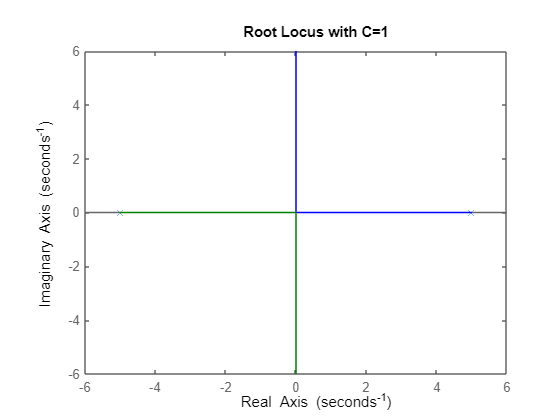

C = 1;
figure;
rlocus(C*G);
title('Root Locus with C=1');

Design with a PD controller

kp = 10;
kd = 1;
C = kp + kd*s;

Plot root locus with PD controller

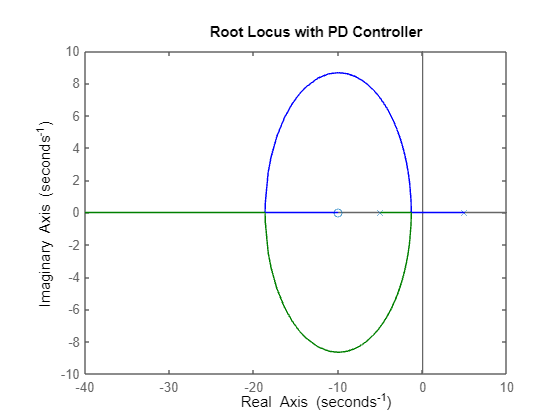

figure;
rlocus(C*G);
title('Root Locus with PD Controller');

Evaluate step response for K=1

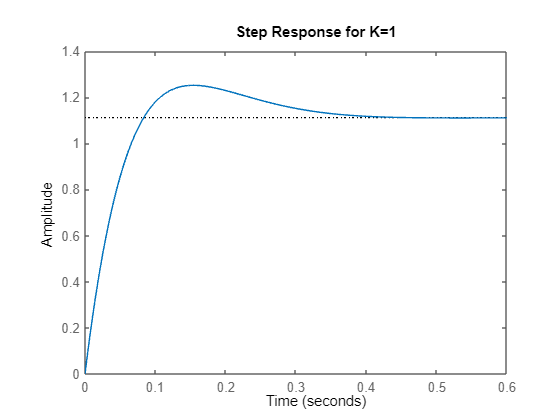

K = 1;
C = K*(kp + kd*s);
GCL = feedback(C*G, 1);
figure;
step(GCL);
title('Step Response for K=1');

Evaluate step response for K=5

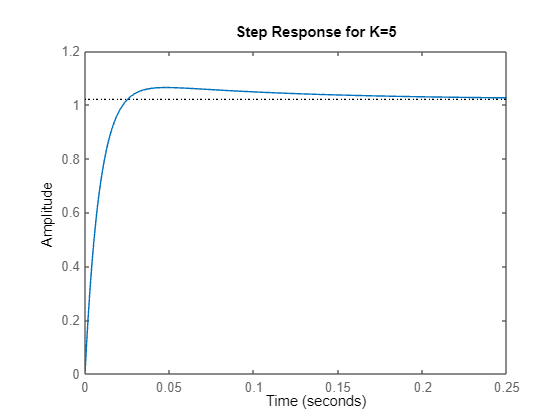

K = 5;
C = K*(kp + kd*s);
GCL = feedback(C*G, 1);
figure;
step(GCL);
title('Step Response for K=5');

Design with PID controller (the I is for zero steady-state error)

ki = 0.1;
C = kp + kd*s + ki/s;

Plot root locus with PID controller 

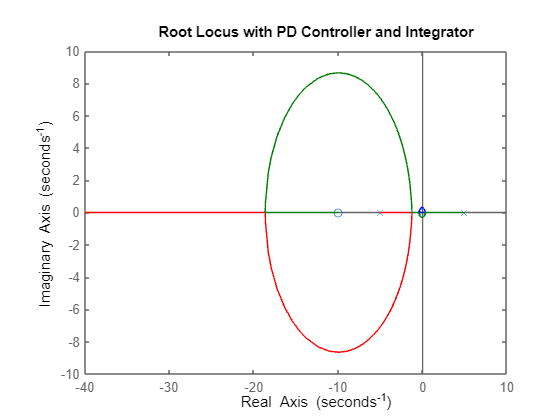

figure;
rlocus(C*G);
title('Root Locus with PD Controller and Integrator');

Evaluate step response with designed K

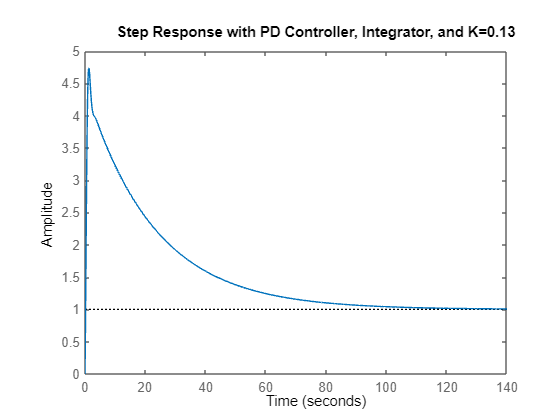

K = 0.13;
C = K*(kp + kd*s + ki/s);
GCL = minreal(feedback(C*G, 1));
figure;
step(GCL);
title('Step Response with PD Controller, Integrator, and K=0.13');